% Hd = fvtool(MuyAgudos3dB);

% Parameters
f = [40 150 600 2500 12e3];
g = [1   0   1   0   0]

g =      1     0     1     0     0


fs = 44100;
cycles = 5;
fref = f(2);
samples = cycles*fs/f(1);

fprintf("fs = %d", fs);

fs = 44100

fprintf("freq = %d %d %d %d %d", f);

freq = 40 150 600 2500 12000

fprintf("gain = %d %d %d %d %d", g);

gain = 1 0 1 0 0


% Signal
n = 1:samples;
% x = zeros([1 samples]);

x = g(1)*cos(2*pi*f(1)*n/fs) + g(2)*cos(2*pi*f(2)*n/fs) + ...
    g(3)*cos(2*pi*f(3)*n/fs) + g(4)*cos(2*pi*f(4)*n/fs) + ...
    g(5)*cos(2*pi*f(5)*n/fs);
y = x;

% Filter selection
h = [MuyGraves3dB.sosMatrix; GravesMenos3dB.sosMatrix; 
    MediosMenos9dB.sosMatrix; Agudos0dB.sosMatrix;
    MuyAgudosMenos9dB.sosMatrix];
k = [transpose(MuyGraves3dB.scaleValues); transpose(GravesMenos3dB.scaleValue); 
    transpose(MediosMenos9dB.scaleValues); transpose(Agudos0dB.scaleValues);
    transpose(MuyAgudosMenos9dB.scaleValues)];

b1 = [];
a1 = [];
b2 = [];
a2 = [];
K = [];

for i = 1:5
    K = [K k(i, 3)]; 
    b1 = [b1; h(2*i-1, 1:3)] * k(i, 1);
    a1 = [a1; h(2*i-1, 4:6)];
    b2 = [b2; h(2*i, 1:3)] * k(i, 2);
    a2 = [a2; h(2*i, 4:6)];
end

disp(b1);

    0.7435   -1.4796    0.7362
    0.9953   -1.9582    0.9643
    0.0928   -0.1749    0.0838
    1.0000         0         0
    0.4125    0.5686    0.2304



disp(a1);

    1.0000   -1.9920    0.9921
    1.0000   -1.9594    0.9611
    1.0000   -1.9536    0.9554
    1.0000         0         0
    1.0000    1.5951    0.6694



disp(b2);

    0.9532   -1.9035    0.9504
    1.0006   -1.9897    0.9893
    1.0234   -2.0000    0.9800
    1.0000         0         0
    1.2411   -0.9798    0.4240



disp(a2);

    1.0000   -1.9971    0.9971
    1.0000   -1.9883    0.9884
    1.0000   -1.7880    0.8200
    1.0000         0         0
    1.0000   -1.1953    0.4496




for i = 1:5
    y = filter(b1(i,:), a1(i,:), y);
    y = filter(b2(i,:), a2(i,:), y); 
    y = K(i) * y;
end    

figure;
hold;

Current plot held


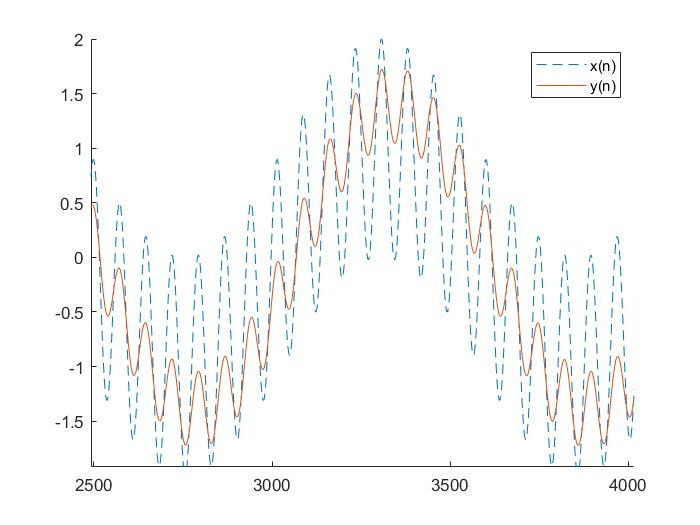

plot(n, x, '--');
plot(n, y(1:length(x)), '-');
legend({'x(n)','y(n)'})